# Symbol Demodulation:  In-Class Exercises

## Computing SNR

In this example, we do a simple SNR calculation.  Consider a system with the parameters below.  For each path loss value, `PLTest(i), `find the SNR value,  SNR(i).  Plot `SNR` vs. `PLTest`.  

Ptx = 23;      % TX power in dBm
bw = 20e6;     % Bandwidth in MHz
PLTest = linspace(40,140,100)';  % Path loss values
NF = 6;   % RX noise figure in dB

% Boltzmann constant and temperature.  Note kT is in Watts not mW!
k = physconst('Boltzmann');
T = 290;  

% TODO:  Find and plot the RX SNR as a function of the PL.
%   SNR = ...

## Simulating Noise in Discrete Symbols

In this exercise, we will show how to add noise to the QAM symbols.  First, create a set of random QAM modulated symbols with the following parameters.

nsym = 1e4;    % number of symbols
bitsPerSym = 4;  % bits per symbol
nbits = bitsPerSym * nsym;

% TODO:  Create random bits and symbol
%   M = ...  % modulation order
%   b = ...  % random bits
%   s = qammod(..., 'UnitAveargePower', true)  % Random symbols.  


% TODO:  Plot the TX constellation



Create received symbols `r=s + w`.  where `w` is AWGN noise set to an SNR of `Es/N0` as shown.  PLot the received constellation.  Overlay the TX constellation.

EsN0 = 15;  % Es/N0 in dB

% TODO:
%   w = ...
%   r = ...
%   plot(...)

## Measuring the BER

MATLAB's commnuication toolbox has an excellent command, [qamdemod](https://www.mathworks.com/help/comm/ref/qamdemod.html), that can be used to demodulate the bits from the noisy symbols.  The syntax we will use is:

Note that you have to provide the average power since it is the reference level.  Use this command to get the estimated bits and find the BER.  At Es/N0 = 15 dB the BER should be ~ 0.45%.

% TODO:
%   bhat = qamdemod(r,M,'OutputType','bit', 'UnitAveragePower', true);
%   ber = ...

The above code measures the BER at a single SNR value.  Now, complete the following code to measure the BER as a function of the SNR, EsN0.

EsN0Test = linspace(5,15,11);  % SNR values to test
ntest = length(EsN0Test);
ber = zeros(ntest,1);

for i = 1:ntest
    EsN0 = EsN0Test(i);

    % TODO:  Create noisy symbols at the desired SNR
    %   w = ...
    %   r = ...

    % TODO:  Estimate the bits and BER
    %   bhat = ...
    %   ber(i) = ...

    % TODO: Print EsN0 and BER

end

% TODO:  Plot ber vs. EsN0Test.  Use semilogy


## Comparing to the Theoretical Value

We can compare the BER we just simulated to the theoretical values.  Proakis and other references show that, at high SNR, the symbol error rate is approximately:

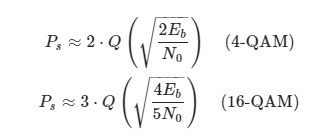

where `Eb/N0` is in linear scale.  With Gray coding, most symbol errors result in only one bit error per symbol.  Hence at high SNR, the  BER is approximately:

`     ber ~= ser / bitsPerSym`

Compute the theoretical BER for the Es/N0 values in `EsN0Theory`.  Plot `berTheory` vs. `EsN0Theory` on the same graph as the simualted values.  You should get a good match.

% Values of Es/N0 to compute the theoretical BER
EsN0Theory = linspace(5,15,100)';

% TODO:  Compute theoretical BER
%   berTheory = ...

% TODO:  Plot the BER vs. EsN0 for theory and simualted.  
% Label your plots


